# [IPSA] - Automatique - Projet drone

# Modelisation d'un drone en representation d'état linéaire

***Etude mécanique (Newtonienne)***

Auteur : Adrien Jacob 

## 1. Identification des variables d'état pour le modèle

### 1.1. Rappel sur les repères de référence du système et relation de passage (angles d'Euler)

        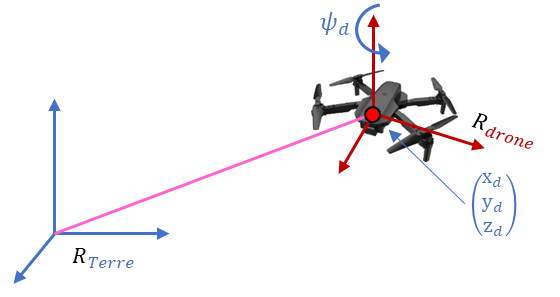               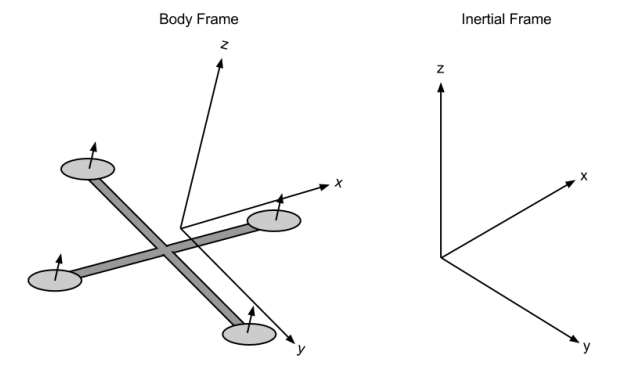

        **Deux repères sont fondamentalement liés au système :**

-         Le repère Inertiel lié à la Terre : $R_T$ : fixe, **c'est le repère de référence pour localiser le drone dans son environnement**

-         Le repère lié au "body" : $R_B$ : qui se déplace en même temps que le drone, **c'est le repère de référence pour modéliser sa dynamique de rotation**

        **Important à comprendre :**

-         La modelisation dynamique de ce système se fera avec une **approche Newtonienne**, une approche Lagrangienne aurait également été possible.

-         L'approche Newtonienne exprimera le comportement dynamique du drone dans $R_T$ (pour les translations) et dans $R_B$ (pour les rotations).

-         Pour modéliser les rotations et leurs impacts en référence à un repère terrestre fixe $R_T$ nous devons utiliser une relation de passage $R_{B\to T}$ non linéaire.

-         L'idée pour simplifier la modélisation est d'écrire les dynamiques de translation et rotation dans les repères où elles sont les plus simples.

-         La force d'une représentation d'état est qu'elle n'est pas unique et peut se formaliser avec plusieurs repères de référence $R_B$ et $R_T$.

-         **Le choix du vecteur d'état permettra de faire cette modélisation astucieuse pour simplifier les équations.**

### 1.2. Définition du passage $R_{B\to T}$

        Pour simplifier la notation, on posera $c:$$\textrm{cosinus}$, $s:$$\textrm{sinus}$, $t:\textrm{tangeante}$ 

        Chaque rotation des angles d'Euler se définit comme suit (résultat très classique en modélisation mécanique)

        $R_{\varphi } =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\varphi  & -s\varphi \\
0 & s\varphi  & c\varphi 
\end{array}\right\rbrack$    ;   $R_{\theta } =\left\lbrack \begin{array}{ccc}
c\theta  & 0 & s\theta \\
0 & 1 & 0\\
-s\theta  & 0 & c\theta 
\end{array}\right\rbrack$    ;   $R_{\psi } =\left\lbrack \begin{array}{ccc}
c\psi  & -s\psi  & 0\\
s\psi  & c\psi  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$

        Nous pouvons utiliser la convention "ZYX" des angles d'Euler qui donne : 

        ${\left\lbrack \begin{array}{c}
\varphi \\
\theta \\
\psi 
\end{array}\right\rbrack }_{\textrm{RT}} =$$R_{\psi }$.$R_{\theta }$.$R_{\varphi }$.${\left\lbrack \begin{array}{c}
\varphi \\
\theta \\
\psi 
\end{array}\right\rbrack }_{\textrm{RB}}$    , avec ${\mathit{\mathbf{R}}}_{\psi }$.${\mathit{\mathbf{R}}}_{\theta } \ldotp$${\mathit{\mathbf{R}}}_{\varphi } ={\mathit{\mathbf{R}}}_{\mathit{\mathbf{B}}\to \mathit{\mathbf{T}}} =\left\lbrack \begin{array}{ccc}
c\psi \ldotp c\theta  & c\psi \ldotp s\theta \ldotp s\varphi -s\psi \ldotp c\varphi  & c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \\
s\psi \ldotp c\theta  & s\psi \ldotp s\theta \ldotp s\varphi +c\psi \ldotp c\varphi  & s\psi \ldotp s\theta \ldotp c\varphi -c\psi \ldotp s\varphi \\
-s\theta  & c\theta \ldotp s\varphi  & c\theta \ldotp c\varphi 
\end{array}\right\rbrack$

### 1.3 Repère de référence pour la position du drone (dans  $R_T$)

        La position du drone est directement issue de la distance par rapport à l'origine du repère $R_T$ pour le localiser

        Avec l'origine positionnée en (0,0,0), on définit simplement la position du repère du drone dans le repère $R_T$ : ${{\left\lbrack x,y,z\right\rbrack }^T }_{|R_T }$

### 1.4 Repère de référence pour l'orientation du drone (dans  $R_T$)

        L'orientation du drone est directement issue des trois rotations successives par rapport à $R_T$ pour le localiser

        En reprenant la convention des angles d'Euler vu en 1.2, on définit simplement l'orientation du drone dans le repère $R_T$ : ${{\left\lbrack \varphi ,\theta ,\psi \right\rbrack }^T }_{|R_T }$

### 1.5 Repère de référence pour la vitesse linéaire du drone (dans  $R_T$ ou $R_B$)

        Deux choix sont possibles :

-         Exprimer la vitesse du drone dans le repère $R_T$, c'est donc la dérivée directe du vecteur position : ${{\left\lbrack \dot{x} ,\dot{y} ,\dot{z} \right\rbrack }^T }_{|R_T }$

-         Exprimer la vitesse du drone dans son propre repère $R_B$ : ${{\left\lbrack u,v,w\right\rbrack }^T }_{|R_B }$, on peut alors retrouver son équivalent dans le repère $R_T$ grâce à la matrice de passage ${{\left\lbrack \dot{x} ,\dot{y} ,\dot{z} \right\rbrack }^T }_{|R_T } =R_{B\to T} \ldotp {{\left\lbrack u,v,w\right\rbrack }^T }_{|R_B }$

        **Les deux sont viables, cependant** Il est souvent plus direct d'utiliser les vitesses exprimées dans le repère $R_T$, car les équations de Newton sont naturellement formulées dans ce repère.

        *(exemple) *la gravité qui s'exprime facilement dans $R_T$ (dirigé selon $-\vec{z}$ et qui impacte de manière significative la dynamique du drone).

### 1.6 Repère de référence pour la vitesse angulaire du drone (dans  $R_B$)

        **Attention** ici, les vitesse de rotation angulaire du drone sont naturellement exprimé dans le repère du drone $R_B$ par les équations de Newton : ${{\left\lbrack p,q,r\right\rbrack }^T }_{|R_B }$ autour des axes du drone ${{\left\lbrack x_B ,y_B ,z_B \right\rbrack }^T }_{|R_B }$

        avec $p$ : vitesse de roulis, $q$ : vitesse de tangage, $r$ : vitesse de lacet.

        **Le point fondamental à comprendre** est que la dynamique de rotation du drone dépend de sa matrice d'inertie, définissant la répartition des masses autour des axes de références.

-         **Dans le repère **$R_B$**, cette matrice d'inertie est constante** car solidaire d'un repère fixe par rapport au drone **et simple** (par la géométrie symétrique du drone)

-         Dans le repère $R_T$, cette matrice est variable dans le temps et complexe à modéliser.

        On considerera alors le vecteur rotation du drone dans son propre repère ${\vec{\Omega} }_{|R_B } ={{\left\lbrack p,q,r\right\rbrack }^T }_{|R_B }$ 

        La relation de passage défini précédemment nous donne un équivalent dans $R_T$ :

        ${\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack }_{|R_B } =\dot{\varphi} \ldotp \left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack +\dot{\theta} \ldotp {R_{\varphi } }^T \ldotp \left\lbrack \begin{array}{c}
0\\
1\\
0
\end{array}\right\rbrack +\dot{\psi} \ldotp {R_{\varphi } }^T \ldotp {R_{\theta } }^T \ldotp \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & -s\theta \\
0 & c\varphi  & s\varphi \ldotp c\theta \\
0 & -s\varphi  & c\varphi \ldotp c\theta 
\end{array}\right\rbrack \ldotp {\left\lbrack \begin{array}{c}
\dot{\varphi} \\
\dot{\theta} \\
\dot{\psi} 
\end{array}\right\rbrack }_{|R_T }$    et en inversant, il vient :   ${\left\lbrack \begin{array}{c}
\dot{\varphi} \\
\dot{\theta} \\
\dot{\psi} 
\end{array}\right\rbrack }_{|R_T } =\left\lbrack \begin{array}{ccc}
1 & s\varphi \ldotp t\theta  & c\varphi \ldotp t\theta \\
0 & c\varphi  & -s\varphi \\
0 & s\varphi /c\theta  & c\varphi /c\theta 
\end{array}\right\rbrack \ldotp {\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack }_{|R_B }$

        soit : 

- 
$$\dot{\varphi} =p+q\ldotp s\varphi \ldotp t\theta +r\ldotp c\varphi \ldotp t\theta$$


- 
$$\dot{\theta} =q\ldotp c\varphi -r\ldotp s\varphi$$


- 
$$\dot{\psi} =q\ldotp s\varphi /c\theta +r\ldotp c\varphi /c\theta$$


### 1.7 Choix du vecteur d'état

        Afin de simplifier la définition de la matrice A de la dynamique du système, nous avons intérêt à choisir des états facilement accessible depuis les lois de Newton.

        Ainsi comme expliqué précédemment, nous prendrons :

-         ${{\left\lbrack x,y,z\right\rbrack }^T }_{|R_T }$ : la position (repère $R_T$) afin de localiser le drone

-         ${{\left\lbrack \varphi ,\theta ,\psi \right\rbrack }^T }_{|R_T }$ : l'orientation (repère $R_T$) afin de localiser le drone

-         ${{\left\lbrack \dot{x} ,\dot{y} ,\dot{z} \right\rbrack }^T }_{|R_T }$ : la vitesse linéaire (repère $R_T$) pour exprimer sa dynamique de translation 

-         ${{\left\lbrack p,q,r\right\rbrack }^T }_{|R_B }$ : la vitesse angulaire (repère $R_B$) pour exprimer sa dynamique de rotation 

        L'état est alors : $x={\left\lbrack x,y,z,\varphi ,\theta ,\psi ,\dot{x} ,\dot{y} ,\dot{z} ,p,q,r\right\rbrack }^T$ **qui est définit dans un espace d'état comprenant les deux repères !**

        On se propose de le réorganiser de manière canonique afin de séparer (par blocs) chaque dynamique et observer plus facilement les couplages :

        
$$x={\left\lbrack x,\dot{x} \;,y,\dot{y} \;,\;z,\dot{z} \;,\;\varphi ,p\;,\;\theta ,q\;,\;\psi ,r\right\rbrack }^T$$


## 2. Détermination des équations différentielles du mouvement (Newton-Euler)

### 2.1. Formulation des théorèmes

#### 2.1.1 Théorème de la résultante

        Exprimons directement le théorème de la résultante dynamique dans le repère $R_T$ :

        
$${{\left\lbrack \ddot{x} ,\ddot{y} ,\ddot{z} \right\rbrack }^T }_{|R_T } =\frac{1}{m}{\sum \vec{F} }_{\textrm{ext}|R_T }$$


#### 2.1.2 Théorème du moment

        Exprimons le théorème du moment dynamique au centre d'inertie $G$ du drone :

        
$$\sum \vec{{M_G }_{\textrm{ext}|R_T } } ={\left(\frac{\mathrm{d}}{\mathrm{d}t}\vec{L_G } \right)}_{|R_T } ={\left(\frac{\mathrm{d}}{\mathrm{d}t}I_T \ldotp {\vec{\Omega} }_{|R_T } \right)}_{|R_T }$$
 

         avec : 

-         $I_T$ la matrice d'inertie en $G$ du drone exprimé dans le repère $R_T$

-         ${\vec{\Omega} }_{|R_T } ={\left\lbrack \dot{\varphi} ,\dot{\theta} ,\dot{\psi} \right\rbrack }_{|R_T }^T$ le vecteur de vitesse angulaire exprimée dans $R_T$

                 Dans ce cas :

                 
$$\sum \vec{{M_G }_{\textrm{ext}|R_T } } =\dot{I_T } \ldotp {\vec{\Omega} }_{|R_T } +I_T \ldotp {\vec{\dot{\Omega} } }_{|R_T }$$
  

                Cette équation n'est pas pratique dans $R_T$ car $\dot{I_T }$ n'est pas nulle et complexifie grandement les équations

**    Exprimons alors cette dynamique dans **$R_B$** :**

          En dérivant le moment d'inertie il vient : ${\left(\frac{\mathrm{d}}{\mathrm{d}t}\vec{L_G } \right)}_{|R_T } ={\left(\frac{\mathrm{d}}{\mathrm{d}t}\vec{L_G } \right)}_{|R_B } +{\vec{\Omega} }_{|R_B } \wedge \vec{L_G }$   

          avec  ${\vec{\Omega} }_{|R_B } ={\left\lbrack p,q,r\right\rbrack }_{|R_B }^T \;$ le vecteur de vitesse angulaire exprimé dans $R_B$ 

         Il vient : ${\left(\frac{\mathrm{d}}{\mathrm{d}t}\vec{L_G } \right)}_{|R_T } =\dot{I_B } \ldotp {\vec{\Omega} }_{|R_B } +I_B \ldotp {\vec{\dot{\Omega} } }_{|R_B } +{\vec{\Omega} }_{|R_B } \wedge \left(I_B \ldotp {\vec{\Omega} }_{|R_B } \right)$ avec cette fois-ci $\dot{I_B }$ nulle car $I_B$ constant dans le repère $R_B$

        ** Finalement : **

        
$$\sum \vec{{M_G }_{\textrm{ext}|R_T } } ={\left(\frac{\mathrm{d}}{\mathrm{d}t}\vec{L_G } \right)}_{|R_T } =I_B \ldotp {\vec{\dot{\Omega} } }_{|R_B } +{\vec{\Omega} }_{|R_B } \wedge \left(I_B \ldotp {\vec{\Omega} }_{|R_B } \right)$$


**         P.S. **L'intérêt principal de décrire la dynamique de rotation dans le repère $R_B$ est de profiter d'une matrice d'inertie $I_B$ diagonale et constante dans le temps car solidaire du repère $R_B$

### 2.2. Définition de la dynamique de translation (exprimée dans $R_T$)

**    Bilan des forces extérieurs subies par le système**

- La gravité directement exprimée dans $R_T$ : $\vec{P_G } ={{\left\lbrack \begin{array}{ccc}
0 & 0 & -\textrm{mg}
\end{array}\right\rbrack }^T }_{|R_T }$ (très simple, raison pour laquelle on choisit $R_T$ comme référence pour la dynamique de translation)

- La force de poussée totale des hélices exprimée dans $R_B$ : $\vec{T} =T_B \ldotp \vec{z_B } =\sum F_{\textrm{Mi}} \ldotp \vec{z_B }$ 

             Pour l'exprimer dans le repère terrestre, on utilise la matrice de passage : $\vec{T_T } =R_{B\to T} \ldotp \vec{T} =\left\lbrack \begin{array}{ccc}
c\psi \ldotp c\theta  & c\psi \ldotp s\theta \ldotp s\varphi -s\psi \ldotp c\varphi  & c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \\
s\psi \ldotp c\theta  & s\psi \ldotp s\theta \ldotp s\varphi +c\psi \ldotp c\varphi  & s\psi \ldotp s\theta \ldotp c\varphi -c\psi \ldotp s\varphi \\
-s\theta  & c\theta \ldotp s\varphi  & c\theta \ldotp c\varphi 
\end{array}\right\rbrack \ldotp {\left\lbrack \begin{array}{c}
0\\
0\\
T
\end{array}\right\rbrack }_{{|R}_B } ={T\ldotp \left\lbrack \begin{array}{c}
c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \\
s\psi \ldotp s\theta \ldotp c\varphi -c\psi \ldotp s\varphi \\
c\theta \ldotp c\varphi 
\end{array}\right\rbrack }_{{|R}_T }$

- La force de trainée aérodynamique s'oppose de manière proportionnelle aux vitesses de translation.

            étant donné que les vitesses de translations sont écrites dans le repère $R_T$, on peut alors les modéliser simplement : $\vec{F_{\textrm{drag},R_T } } =\left\lbrack \begin{array}{ccc}
-k_{\textrm{vx}}  & 0 & 0\\
0 & -k_{\textrm{vy}}  & 0\\
0 & 0 & -k_{\textrm{vz}} 
\end{array}\right\rbrack \ldotp {\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack }_{{|R}_T }$.

            **remarque** : Il serait plus juste d'exprimer ces forces dans le repère du drone et de réaliser la relation de passage pour tenir compte de l'aérodynamisme variant en fonction de l'angle d'attaque du drone.

            Etant donné la symétrie du système et la faible influence de ces forces par rapport au reste, il convient d'accepter : $\vec{F_{\textrm{drag},R_T } } =\left\lbrack \begin{array}{ccc}
-k_{\textrm{vx}}  & 0 & 0\\
0 & -k_{\textrm{vy}}  & 0\\
0 & 0 & -k_{\textrm{vz}} 
\end{array}\right\rbrack \ldotp {\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack }_{{|R}_T } \approx R_{B\to T} \ldotp \left\lbrack \begin{array}{ccc}
-k_u  & 0 & 0\\
0 & -k_v  & 0\\
0 & 0 & -k_w 
\end{array}\right\rbrack \ldotp {\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack }_{{|R}_B }$

**    Finalement, en appliquant le théorème de la résultante dans **$R_T$** :**

        
$$\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} \\
\ddot{z} 
\end{array}\right\rbrack =-g\ldotp \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack +\frac{T}{m}\left\lbrack \begin{array}{c}
c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \\
s\psi \ldotp s\theta \ldotp c\varphi -c\psi \ldotp s\varphi \\
c\theta \ldotp c\varphi 
\end{array}\right\rbrack -\frac{1}{m}\ldotp \left\lbrack \begin{array}{c}
k_{\textrm{vx}} \ldotp \dot{x} \\
k_{\textrm{vy}} \ldotp \dot{y} \\
k_{\textrm{vz}} \ldotp \dot{z} 
\end{array}\right\rbrack$$


        En projetant sur les 3 axes :

-         
$$\ddot{x} =\frac{1}{m}\ldotp \left(T\left(c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \right)-k_{\textrm{vx}} \ldotp \dot{x} \right)$$


-         
$$\ddot{y} =\frac{1}{m}\ldotp \left(T\left(s\psi \ldotp s\theta \ldotp c\varphi -c\psi \ldotp s\varphi \right)-k_{\textrm{vy}} \ldotp \dot{y} \right)$$


-         
$$\ddot{z} =\frac{1}{m}\ldotp \left(T\left(c\theta \ldotp c\varphi \right)-k_{\textrm{vz}} \ldotp \dot{z} -\textrm{mg}\right)$$


        **P.S. **Ces équations montrent clairement le couplage entre l'attitude horizontale du drone ($\varphi ,\theta$) et son accélération linéaire ($\ddot{x} ,\ddot{y}$). 

        Le drone ne peut accélérer horizontalement $\left(\ddot{x} ,\ddot{y} \right)\not= \left(0,0\right)$ que si $T\not= 0$ et s'il est incliné $\left(\varphi ,\theta \right)\not= \left(0,0\right)$.

### 2.3. Définition de la dynamique de rotation (exprimée dans $R_B$)

**    Bilan des moments extérieurs subis par le système : **

- Les couples sur les axes du drone ${\left\lbrack x_B ,y_B ,z_B \right\rbrack }^T$ générés par les hélices : $\vec{C_B } ={\left\lbrack \begin{array}{ccc}
C_{\varphi }  & C_{\theta }  & C_{\psi } 
\end{array}\right\rbrack }_{{|R}_B }^T$ (qui s'exprime simplement dans $R_B$)

- Le couple de trainée aérodynamique lié à la résistance de l'air à la rotation. On peut le modéliser simplement dans $R_B$ : $\vec{C_{\textrm{drag},R_B } } =\left\lbrack \begin{array}{ccc}
-k_p  & 0 & 0\\
0 & -k_q  & 0\\
0 & 0 & -k_r 
\end{array}\right\rbrack \ldotp {\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack }_{{|R}_B }$

- Les moments gyroscopiques liés à la rotation rapide des hélices lorsque le drone lui-même tourne. Cette force est souvent modélisée simplement par $\vec{\Gamma} =I_r \ldotp \left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack \wedge \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \ldotp \vec{\Omega_r }$ **(admis)**

            avec $\vec{\Omega_r }$ : vitesse de rotation de l'hélice et $I_r$ : moment d'inertie autour de l'axe de rotation de l'hélice.

            On considèrera $\vec{\Gamma} =\vec{0}$ par souci de simplicité étant donné que c'est un effet dynamique très minime sur le système en comparaison avec le reste.

**    Définition de la matrice d'inertie **$I_B$

        Par symétrie du drone autour de son centre de gravité G, on a déjà défini $I_B =\left\lbrack \begin{array}{ccc}
I_x  & 0 & 0\\
0 & I_y  & 0\\
0 & 0 & I_z 
\end{array}\right\rbrack$ diagonale et constant dans le temps car solidaire de $R_B$

        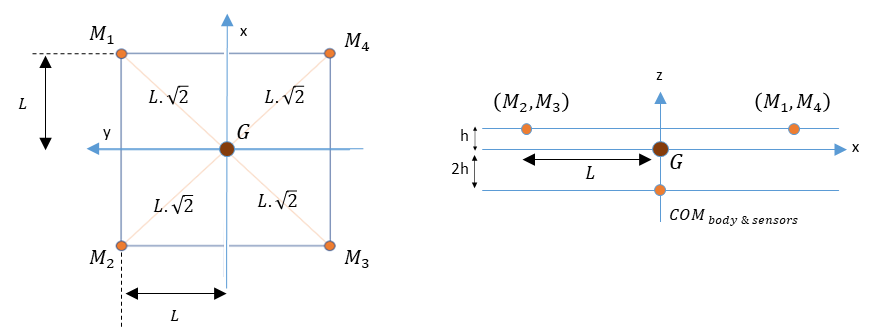

        **P.S.** pour un design en "X" du drone, on a également par symétrie $I_x =I_y$

       ** Théorème du moment dynamique dans **$R_B$** :**

        
$$\sum \vec{{M_G }_{\textrm{ext}|R_B } } =\vec{C_B } +\vec{C_{\textrm{drag},R_B } } +\vec{0} =I_B \ldotp {\vec{\dot{\Omega} } }_{|R_B } +{\vec{\Omega} }_{|R_B } \wedge \left(I_B \ldotp {\vec{\Omega} }_{|R_B } \right)$$


        puis en isolant ${\vec{\dot{\Omega} } }_{|R_B }$ :

        
$${\vec{\dot{\Omega} } }_{|R_B } =\left\lbrack \begin{array}{c}
\dot{p} \\
\dot{q} \\
\dot{r} 
\end{array}\right\rbrack ={I_B }^{-1} \ldotp \left(-\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack \wedge \left\lbrack \begin{array}{c}
I_x \ldotp p\\
I_y \ldotp q\\
I_z \ldotp r
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
k_p \\
k_q \\
k_r 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
C_{\varphi } \\
C_{\theta } \\
C_{\psi } 
\end{array}\right\rbrack \right)$$


        En projetant sur les 3 axes :

-         
$$\dot{p} =\frac{1}{I_x }\left(\left(I_y -I_z \right)\ldotp \textrm{qr}-k_p \ldotp p+C_{\varphi } \right)$$


-         
$$\dot{q} =\frac{1}{I_y }\left(\left(I_z -I_x \right)\ldotp \textrm{pr}-k_q \ldotp q+C_{\theta } \right)$$


-         
$$\dot{r} =\frac{1}{I_z }\left(\left(I_x -I_y \right)\ldotp \textrm{qp}-k_r \ldotp r+C_{\psi } \right)$$


### 2.4. Synthèse de l'approche Newtonienne :

        Dynamique de translation dans $R_T$ :

        
$$\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} \\
\ddot{z} 
\end{array}\right\rbrack =-g\ldotp \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack -\frac{1}{m}\ldotp \left\lbrack \begin{array}{c}
k_{\textrm{vx}} \\
k_{\textrm{vy}} \\
k_{\textrm{vz}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack +\frac{T}{m}\left\lbrack \begin{array}{c}
c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \\
s\psi \ldotp s\theta \ldotp c\varphi -c\psi \ldotp s\varphi \\
c\theta \ldotp c\varphi 
\end{array}\right\rbrack$$


        Dynamique de rotation dans $R_B$ :

        
$$\left\lbrack \begin{array}{c}
\dot{p} \\
\dot{q} \\
\dot{r} 
\end{array}\right\rbrack ={I_B }^{-1} \ldotp \left(-\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack \wedge \left\lbrack \begin{array}{c}
I_x \ldotp p\\
I_y \ldotp q\\
I_z \ldotp r
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
k_p \\
k_q \\
k_r 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
C_{\varphi } \\
C_{\theta } \\
C_{\psi } 
\end{array}\right\rbrack \right)$$


        On retrouve :

- les états : $x={\left\lbrack x,\dot{x} \;,y,\dot{y} \;,\;z,\dot{z} \;,\;\varphi ,p\;,\;\theta ,q\;,\;\psi ,r\right\rbrack }^T$

- les entrées : $u={\left\lbrack \begin{array}{cccc}
T & C_{\varphi }  & C_{\theta }  & C_{\psi } 
\end{array}\right\rbrack }^T$

### 2.5. Lien avec les entrées réelles du drone ($\omega_{\textrm{Mi}}$)

        Reste maintenant à relier les termes de force $T$ et de couple $\left(C_{\varphi } ,C_{\theta } ,C_{\psi } \right)$ aux commandes réelles du système, qui sont les vitesses angulaires des rotors $\omega_{\textrm{Mi}}$.

        Nous choisissons de considérer **un modèle de rapport proportionnel constant entre **$T$** et **${\omega_{\textrm{Mi}} }^2$** :**

-         $T=\sum F_{\textrm{Mi}} =\sum k_t \ldotp \omega_{\textrm{Mi}}^2$ selon $\vec{z_{R_B } }$     , avec $k_t =\frac{1}{2}Q_{\textrm{air}} \ldotp \pi \ldotp r^2$ une constante qui dépend de la quantité d'air et du profil des hélices.

-         $C_{\psi ,\textrm{Mi}} =k_c \ldotp {\omega_{\textrm{Mi}} }^2 \;$ où $k_c$ est le coefficient de trainée aérodynamique des pales considéré constant

        Ainsi, avec la position des moteurs M1 à M4 proposé en 2.3, on met en évidence en ramenant tout les moments et coupes en $G$, centre du repère $R_B$ :

-         pour le trust :    $T=k_t \ldotp \left(+\omega_{\textrm{M1}}^2 +\omega_{\textrm{M2}}^2 +\omega_{\textrm{M3}}^2 +\omega_{\textrm{M4}}^2 \right)$ selon $\vec{z_{R_B } }$

-         pour le pitch :  $C_{\varphi } =L\ldotp k_t \ldotp \left(+\omega_{\textrm{M1}}^2 +\omega_{\textrm{M2}}^2 -\omega_{\textrm{M3}}^2 -\omega_{\textrm{M4}}^2 \right)$ selon $\vec{x_{R_B } }$

-         pour le roll :     $C_{\theta } =L\ldotp k_t \ldotp \left(-\omega_{\textrm{M1}}^2 +\omega_{\textrm{M2}}^2 +\omega_{\textrm{M3}}^2 -\omega_{\textrm{M4}}^2 \right)$ selon $\vec{y_{R_B } }$

-         pour le yaw :   $C_{\psi } =k_c \ldotp \left(+\omega_{\textrm{M1}}^2 -\omega_{\textrm{M2}}^2 +\omega_{\textrm{M3}}^2 -\omega_{\textrm{M4}}^2 \right)$ selon $\vec{z_{R_B } }$

        Il vient en écriture matricielle (on pose $k_m =$$\frac{k_c }{k_t }$) :

        
$$\left\lbrack \begin{array}{c}
T\\
C_{\varphi } \\
C_{\theta } \\
C_{\psi } 
\end{array}\right\rbrack =k_t \ldotp \left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
-L & L & L & -L\\
-L & -L & L & L\\
{-k}_m  & k_m  & -k_m  & k_m 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
{\omega_1 }^2 \\
{\omega_2 }^2 \\
{\omega_3 }^2 \\
{\omega_4 }^2 
\end{array}\right\rbrack =M\ldotp \left\lbrack \begin{array}{c}
{\omega_1 }^2 \\
{\omega_2 }^2 \\
{\omega_3 }^2 \\
{\omega_4 }^2 
\end{array}\right\rbrack$$


**        P.S. **Cette relation est simple par construction et design du drone en "X"

## 3. Définition des entrées et sorties du système

### 3.1. Définition des entrées

        **Les entrées réelles** du système sont les vitesses de rotations des hélices $\omega_i^2$

        On peut donc intuitivement considérer le vecteur d'entrée fondamental des moteurs : $u_M ={\left\lbrack \begin{array}{cccc}
{\omega_1 }^2  & {\omega_2 }^2  & {\omega_3 }^2  & {\omega_4 }^2 
\end{array}\right\rbrack }^T$

        Cependant, à la vue des équations différentielles, il est plus intuitif de considérer **des entrées virtuelles** représentant les résultantes dynamiques globale $T$ et $C_B$ :

        Ainsi on construit le vecteur d'entrée virtuel suivant : $u=u_v ={\left\lbrack \begin{array}{cccc}
T & C_{\varphi }  & C_{\theta }  & C_{\psi } 
\end{array}\right\rbrack }^T$

        La relation de passage entre $u$ et $u_M$ a été établit précédemment (2.5) et dépend de $L,k_t ,k_m$ :

        
$$\left\lbrack \begin{array}{c}
T\\
C_{\varphi } \\
C_{\theta } \\
C_{\psi } 
\end{array}\right\rbrack =M\ldotp \left\lbrack \begin{array}{c}
{\omega_1 }^2 \\
{\omega_2 }^2 \\
{\omega_3 }^2 \\
{\omega_4 }^2 
\end{array}\right\rbrack$$


- On peut démontrer que la matrice $M\ldotp M^T$est diagonale : $M\ldotp M^T =\frac{{k_t }^2 }{4}\ldotp \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & L^2  & 0 & 0\\
0 & 0 & L^2  & 0\\
0 & 0 & 0 & {k_m }^2 
\end{array}\right\rbrack$

- Ceci prouve que les 4 canaux de commandes sont parfaitement découplés.

- Ainsi il existe toujours une combinaison spécifique de vitesses moteurs permettant de produire l'une des entrées viruelles, sans modifier les autres !

- Dans la réalité, cette simplicité mathématique n'est pas exacement vrai, mais on peut prendre en compte les irrégularitées de symétrie dans notre commande du moment que $M$ est inversible.

### 3.2. Définition des sorties

        L'ensemble des sorties du système sont liées à sa capacité à connaître à l'instant t, les états du système.

        **Nous ferons ici l'hypothèse que l'ensemble des capteurs permettent de fournir l'ensemble des valeurs de l'état à chaque instant.**

-         Les défauts éventuels des capteurs pourront toujours être considérés comme une perturbation sur l'état que notre commande robuste devra compenser

-         Si certains états ne sont pas disponibles à la lecture par les capteurs, on considérera qu'un observateur d'état permet de les reconstruire suffisamment rapidement *(programme A4-spé)*

        **Ainsi, l'ensemble des sorties du système = l'ensemble des états **

        
$$y=x={\left\lbrack x,\dot{x} \;,y,\dot{y} \;,\;z,\dot{z} \;,\;\varphi ,p\;,\;\theta ,q\;,\;\psi ,r\right\rbrack }^T$$


## 4. Fonction d'état et linéarisation

### 4.1. Formalisation de la fonction d'état

        **En réunissant les résultats trouvés précédemment**, on détermine le jeu des douze équations différentielles : 

        $\dot{x} ={\left\lbrack \dot{x} ,\ddot{x} \;,\dot{y} ,\ddot{y} \;,\;\dot{z} ,\ddot{z} \;,\dot{\varphi} ,\dot{p} \;,\dot{\theta} ,\dot{q} \;,\dot{\psi} ,\dot{r} \right\rbrack }^T$ en fonction de $x$ et $u$ :

-         
$$\dot{x} =\dot{x}$$


-         
$$\ddot{x} =\frac{u_1 }{m}\left(\left(c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \right)-k_{\textrm{vx}} \ldotp \dot{x} \right)$$


-         
$$\dot{y} =\dot{y}$$


-         
$$\ddot{y} =\frac{u_1 }{m}\left(\left(s\psi \ldotp s\theta \ldotp c\varphi -c\psi \ldotp s\varphi \right)-k_{\textrm{vy}} \ldotp \dot{y} \right)$$


-         
$$\dot{z} =\dot{z}$$


-         
$$\ddot{z} =\frac{u_1 }{m}\ldotp \left(\left(c\theta \ldotp c\varphi \right)-k_{\textrm{vz}} \ldotp \dot{z} -\textrm{mg}\right)$$


-         
$$\dot{\varphi} =p+q\ldotp s\varphi \ldotp t\theta +r\ldotp c\varphi \ldotp t\theta$$


-         
$$\dot{p} =\frac{1}{I_x }\left(\left(I_y -I_z \right)\ldotp \textrm{qr}-k_p \ldotp p+u_2 \right)$$


-         
$$\dot{\theta} =q\ldotp c\varphi -r\ldotp s\varphi$$


-         
$$\dot{q} =\frac{1}{I_y }\left(\left(I_z -I_x \right)\ldotp \textrm{pr}-k_q \ldotp q+u_3 \right)$$


-         
$$\dot{\psi} =q\ldotp s\varphi /c\theta +r\ldotp c\varphi /c\theta$$


-         
$$\dot{r} =\frac{1}{I_z }\left(\left(I_x -I_y \right)\ldotp \textrm{qp}-k_r \ldotp r+u_4 \right)$$


        On peut maintenant synthétiser la relation d'état $\dot{x} =f\left(x,u\right)$ de la manière suivante :

        
$$f\left(x,u\right)=\left(\begin{array}{c}
f_1 \left(x,u\right)\\
f_2 \left(x,u\right)\\
f_3 \left(x,u\right)\\
f_4 \left(x,u\right)\\
f_5 \left(x,u\right)\\
f_6 \left(x,u\right)\\
f_7 \left(x,u\right)\\
f_8 \left(x,u\right)\\
f_9 \left(x,u\right)\\
f_{10} \left(x,u\right)\\
f_{11} \left(x,u\right)\\
f_{12} \left(x,u\right)
\end{array}\right)=\left(\begin{array}{c}
\dot{x} \\
\frac{u_1 }{m}\left(\left(c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \right)-k_{\textrm{vx}} \ldotp \dot{x} \right)\\
\dot{y} \\
\frac{u_1 }{m}\left(\left(s\psi \ldotp s\theta \ldotp c\varphi -c\psi \ldotp s\varphi \right)-k_{\textrm{vy}} \ldotp \dot{y} \right)\\
\dot{z} \\
\frac{u_1 }{m}\ldotp \left(\left(c\theta \ldotp c\varphi \right)-k_{\textrm{vz}} \ldotp \dot{z} -\textrm{mg}\right)\\
p+q\ldotp s\varphi \ldotp t\theta +r\ldotp c\varphi \ldotp t\theta \\
\frac{1}{I_x }\left(\left(I_y -I_z \right)\ldotp \textrm{qr}-k_p \ldotp p+u_2 \right)\\
q\ldotp c\varphi -r\ldotp s\varphi \\
\frac{1}{I_y }\left(\left(I_z -I_x \right)\ldotp \textrm{pr}-k_q \ldotp q+u_3 \right)\\
q\ldotp s\varphi /c\theta +r\ldotp c\varphi /c\theta \\
\frac{1}{I_z }\left(\left(I_x -I_y \right)\ldotp \textrm{qp}-k_r \ldotp r+u_4 \right)
\end{array}\right)$$


        Cette fonction d'état ne peut pas être modélisée en représentation de la forme $\dot{x} =\textrm{Ax}+\textrm{Bu}$ avec $A$ et $B$ constante car elle contient : 

-         Des fonctions trigonométriques des états

-         Des produits d'états (par exemple, $\textrm{qr},\textrm{pr},\textrm{qp}$ dans les équations de rotation).

-         Des divisions par des fonctions d'états ($c\theta$ dans l'équation pour $\dot{\psi}$).

-         Des multiplications des entrées $u_i$ par des fonctions trigonométriques des états.

### 4.2. Linéarisation de la fonction d'état

        L'idée est donc de considérer un point de fonctionnement stable du système autour duquel nous voulons le contrôler puis de linéariser les équations autour de ce point avec un développement de Taylor d'ordre 1.

        Le modèle linéaire obtenu ne sera alors valide qu'autour de ce point de fonctionnement stable.

        Il est nécessaire de définir l'état stable $x_e$ et la commande $u_e$ qui permet de l'obtenir.

#### 4.2.1 Choix d'un état stable $x_e$

        La logique voudrait que l'on choisisse l'état stable par défaut du système, c'est à dire la configuration "hover" (vol stationnaire) où le drone est fixe dans le repère $R_T$

        Dans ce cas,définissons l'état d'équilibre $x_e$ correspondant au vol stationnaire à une position $\left(x_0 ,y_0 ,z_0 \right)$ avec une orientation horizontale $\left(\varphi_e =0,\theta_e =0\right)$ et un cap $\psi_e$ (prennons par exemple $\psi_e =0$ pour simplifier) :

-         Position : $\left\lbrack \begin{array}{ccc}
x_e =x_0  & y_e =y_0  & z_e =z_0 
\end{array}\right\rbrack$

-         Vitesses linéaires : $\left\lbrack \begin{array}{ccc}
\dot{x_e } =0 & \dot{y_e } =0 & \dot{z_e } =0
\end{array}\right\rbrack$

-         Angles d'Euler : $\left\lbrack \begin{array}{ccc}
\varphi_e =0 & \theta_e =0 & \psi_e =0
\end{array}\right\rbrack$

-         Vitesses angulaires : $\left\lbrack \begin{array}{ccc}
p_e =0 & q_e =0 & r_e =0
\end{array}\right\rbrack$

        Ainsi $x_e ={\left\lbrack x_0 ,0,y_0 ,0,z_0 ,0,0,0,0,0,0,0\right\rbrack }^T$

#### 4.4.2 Détermination de la commande stabilisante $u_e$

        Identifions maintenant la commande $u_e ={\left\lbrack \begin{array}{cccc}
T_e  & {C_{\varphi } }_e  & {C_{\theta } }_e  & {C_{\psi } }_e 
\end{array}\right\rbrack }^T$ permettant de maintenir le drone à son équilibre.

        Pour cela nous reprenons les équations différentielles en remplaçant $x=x_e$

        Il vient :

        
$$\left\lbrack \begin{array}{c}
{\ddot{x} }_e \\
{\ddot{y} }_e \\
{\ddot{z} }_e 
\end{array}\right\rbrack =-g\ldotp \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack -\frac{1}{m}\ldotp \left\lbrack \begin{array}{c}
k_{\textrm{vx}} \\
k_{\textrm{vy}} \\
k_{\textrm{vz}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{x} }_e \\
{\dot{y} }_e \\
{\dot{z} }_e 
\end{array}\right\rbrack +\frac{1}{m}\left\lbrack \begin{array}{c}
c\psi_e \ldotp s\theta_e \ldotp c\varphi_e +s\psi_e \ldotp s\varphi_e \\
s\psi_e \ldotp s\theta_e \ldotp c\varphi_e -c\psi_e \ldotp s\varphi_e \\
c\theta_e \ldotp c\varphi_e 
\end{array}\right\rbrack \ldotp u_{1e}$$


        
$$\left\lbrack \begin{array}{c}
{\dot{p} }_e \\
{\dot{q} }_e \\
{\dot{r} }_e 
\end{array}\right\rbrack ={I_B }^{-1} \ldotp \left(-\left\lbrack \begin{array}{c}
p_e \\
q_e \\
r_e 
\end{array}\right\rbrack \wedge \left\lbrack \begin{array}{c}
I_x \ldotp p_e \\
I_y \ldotp q_e \\
I_z \ldotp r_e 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
k_p \\
k_q \\
k_r 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
p_e \\
q_e \\
r_e 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
u_{2e} \\
u_{3e} \\
u_{4e} 
\end{array}\right\rbrack \right)$$


        En remplaçant avec $x_e ={\left\lbrack x_0 ,0,y_0 ,0,z_0 ,0,0,0,0,0,0,0\right\rbrack }^T$ :

        
$$\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack =-g\ldotp \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack -\frac{1}{m}\ldotp \left\lbrack \begin{array}{c}
k_{\textrm{vx}} \\
k_{\textrm{vy}} \\
k_{\textrm{vz}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack +\frac{1}{m}\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \ldotp u_{1e}$$


        
$$\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack ={I_B }^{-1} \ldotp \left(\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
u_{2e} \\
u_{3e} \\
u_{4e} 
\end{array}\right\rbrack \right)$$


        **On voit alors que l'état d'équilibre choisi (le vol stationnaire) est respecté pour **$u_{1e} =m\ldotp g$** sur l'axe **${\vec{z} }_{\textrm{RT}}$

        On retrouve bien un résultat cohérent : l'équilibre est atteint avec le poids du drone compensé équitablement sur les 4 moteurs.

#### 4.4.3 Linéarisation autour du point de fonctionnement $\left(x_e ,u_e \right)$

        Pour déterminer la matrice d'état linéarisée $A_{\textrm{lin}}$, il est nécessaire de réaliser les dérivées partielles de tout les états vers tout les états.

        Il en résulte 12*12 = 144 calcul de dérivées partielles qui heuresement sont la plupart du temps nulles autour de $\left(x_e ,u_e \right)$ :

        
$$A_{\textrm{lin}}$$

$$=\left\lbrack \begin{array}{ccccc}
\frac{\partial }{\partial x}f_1 \left(x_e ,u_e \right) & \frac{\partial }{\partial \dot{x} }f_1 \left(x_e ,u_e \right) & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \frac{\partial }{\partial r}f_1 \left(x_e ,u_e \right)\\
\frac{\partial }{\partial x}f_2 \left(x_e ,u_e \right) & \frac{\partial }{\partial \dot{x} }f_2 \left(x_e ,u_e \right) & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \frac{\partial }{\partial r}f_2 \left(x_e ,u_e \right)\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{\partial }{\partial x}f_{12} \left(x_e ,u_e \right) & \frac{\partial }{\partial \dot{x} }f_{12} \left(x_e ,u_e \right) & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \frac{\partial }{\partial r}f_{12} \left(x_e ,u_e \right)
\end{array}\right\rbrack$$


        On réalise ensuite les mêmes étapes pour $B_{\textrm{lin}}$ en dérivant partiellement tout les états en fonction de toutes les entrées : 

        
$$B_{\textrm{lin}}$$

$$=\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial u_1 }f_1 \left(x_e ,u_e \right) & \ldotp \ldotp \ldotp  & \frac{\partial }{\partial u_4 }f_1 \left(x_e ,u_e \right)\\
\frac{\partial }{\partial u_1 }f_2 \left(x_e ,u_e \right) & \ldotp \ldotp \ldotp  & \frac{\partial }{\partial u_4 }f_2 \left(x_e ,u_e \right)\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{\partial }{\partial u_1 }f_{12} \left(x_e ,u_e \right) & \ldotp \ldotp \ldotp  & \frac{\partial }{\partial u_4 }f_{12} \left(x_e ,u_e \right)
\end{array}\right\rbrack$$


        **Exemple : **

        Pour comprendre l'influence de cette linéarisation, prenons l'exemple des dérivées partielles de $\ddot{x}$ autour de $\left(x_e ,u_e \right)$ :

-         
$$\frac{\partial }{\partial \theta }f_2 \left(x,u\right)=\frac{\partial }{\partial \theta }\left(\frac{1}{m}\ldotp \left(u_1 \ldotp \left(c\psi \ldotp s\theta \ldotp c\varphi +s\psi \ldotp s\varphi \right)-k_{\textrm{vx}} \ldotp \dot{x} \right)\right)=\frac{\partial }{\partial \theta }\left(\frac{1}{m}\ldotp \left(u_1 \ldotp \left(c\psi \ldotp s\theta \ldotp c\varphi +0\right)-0\right)\right)=\frac{u_1 }{m}c\psi \ldotp c\varphi \ldotp c\theta$$


-         évalué pour $\left(x_e ,u_e \right)$, cela donne : $\frac{\partial }{\partial \theta }\ddot{x} \;\left(x_e ,u_e \right)=\frac{u_{1e} }{m}c\psi_e \ldotp c\varphi_e \ldotp c\theta_e =\frac{\textrm{mg}}{m}\ldotp 1\ldotp 1\ldotp 1=g$

-         De même pour $\frac{\partial }{\partial \dot{x} }f_2 \;\left(x_e ,u_e \right)=-k_{\textrm{vx}}$

        Toutes les autres dérivées partielles de $\ddot{x}$ sont nulles ainsi : $\ddot{x} \approx g\ldotp \theta -k_{\textrm{vx}} \ldotp \dot{x}$ (à la constante d'intégration des C.I. près)

#### 4.4.4 Détermination de la matrice d'état linéarisée : $A$

        On réalise les mêmes opérations pour tout les états en fonction de tout les états et on obtient notablement :

-         $\dot{x} =\dot{x}$   ;   $\ddot{x} =g\ldotp \theta -\frac{k_{\textrm{vx}} }{m}\ldotp \dot{x}$   ;   $\dot{y} =\dot{y}$   ;   $\ddot{y} =-g\ldotp \varphi -\frac{k_{\textrm{vy}} }{m}\ldotp \dot{y}$   ;   $\dot{z} =\dot{z}$   ;   $\ddot{z} =-\frac{k_{\textrm{vz}} }{m}\ldotp \dot{z}$

-         $\dot{\varphi} =p$  ;   $\dot{p} =-\frac{k_p }{I_x }\ldotp p$             ;   $\dot{\theta} =q$   ;    $\dot{q} =-\frac{k_q }{I_y }\ldotp q$           ;   $\dot{\psi} =r$   ;   $\dot{r} =-\frac{k_r }{I_z }\ldotp r$

        La matrice $A$ linéarisée résultante de la dynamique d'état : $\dot{x} =A\ldotp x$ donne : 

        $\left(\begin{array}{c}
\dot{x} \\
\ddot{x} \\
\dot{y} \\
\ddot{y} \\
\dot{z} \\
\ddot{z} \\
\dot{\varphi} \\
\dot{p} \\
\dot{\theta} \\
\dot{q} \\
\dot{\psi} \\
\dot{r} 
\end{array}\right)=\left(\begin{array}{cccccccccccc}
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right)\ldotp \left(\begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} \\
z\\
\dot{z} \\
\varphi \\
p\\
\theta \\
q\\
\psi \\
r
\end{array}\right)$ ***(à remplir)***

#### 4.4.5 Détermination de la matrice d'entrée linéarisée : $B$

        On réalise les mêmes opérations  mais en dérivant l'état par rapport aux variables d'entrée $u={\left\lbrack \begin{array}{cccc}
u_1  & u_2  & u_3  & u_4 
\end{array}\right\rbrack }^T$

-         $\dot{x} =0$   ;   $\ddot{x} =0$   ;   $\dot{y} =0$   ;   $\ddot{y} =0$   ;   $\dot{z} =0$   ;    $\ddot{z} =\frac{u_1 }{m}$

-         $\dot{\varphi} =0$   ;   $\dot{p} =\frac{u_2 }{I_x }$ ;   $\dot{\theta} =0$   ;   $\dot{q} =\frac{u_3 }{I_y }$  ;   $\dot{\psi} =0$   ;   $\dot{r} =\frac{u_4 }{I_z }$

        La matrice $B$ linéarisée résultante de la dynamique des entrées : $\dot{x} =B\ldotp u$ donne : 

        $\left(\begin{array}{c}
\dot{x} \\
\ddot{x} \\
\dot{y} \\
\ddot{y} \\
\dot{z} \\
\ddot{z} \\
\dot{\varphi} \\
\dot{p} \\
\dot{\theta} \\
\dot{q} \\
\dot{\psi} \\
\dot{r} 
\end{array}\right)$=$\left(\begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right)\ldotp \left\lbrack \begin{array}{c}
T\\
C_{\varphi } \\
C_{\theta } \\
C_{\psi } 
\end{array}\right\rbrack =B\ldotp u$   ***(à remplir)***

        Si l'on veut exprimer le système en fonction des entrées moteur ${\mathit{\mathbf{u}}}_{\mathit{\mathbf{M}}}$ , il suffit de modifier la matrice $B$ :

        
$$B\ldotp M\ldotp \left\lbrack \begin{array}{c}
{\omega_1 }^2 \\
{\omega_2 }^2 \\
{\omega_3 }^2 \\
{\omega_4 }^2 
\end{array}\right\rbrack =B_{\textrm{mot}} \ldotp \left\lbrack \begin{array}{c}
{\omega_1 }^2 \\
{\omega_2 }^2 \\
{\omega_3 }^2 \\
{\omega_4 }^2 
\end{array}\right\rbrack$$


#### 4.4.6 Détermination des matrices linéarisées : $C$ et $D$

        La matrice d'observation $C$ représente les états qui sont lus par les capteurs.

        Comme expliqué précédemment, en imaginant le système muni d'un nombre important de capteurs, on pourrait rendre le système observable et utiliser un observateur pour estimer les états manquant.

        **Supposons cette hypothèse vérifiée**, dans ce cas, la matrice $C=I_d$ identité capture l'ensemble des états $x$ et l'on a $y=x$ :

        
$$y=$$

$$\left(\begin{array}{cccccccccccc}
1 &  &  &  &  &  &  &  &  &  &  & \\
 & 1 &  &  &  &  &  &  & \left(0\right) &  &  & \\
 &  & 1 &  &  &  &  &  &  &  &  & \\
 &  &  & 1 &  &  &  &  &  &  &  & \\
 &  &  &  & 1 &  &  &  &  &  &  & \\
 &  &  &  &  & 1 &  &  &  &  &  & \\
 &  &  &  &  &  & 1 &  &  &  &  & \\
 &  &  &  &  &  &  & 1 &  &  &  & \\
 &  & \left(0\right) &  &  &  &  &  & 1 &  &  & \\
 &  &  &  &  &  &  &  &  & 1 &  & \\
 &  &  &  &  &  &  &  &  &  & 1 & \\
 &  &  &  &  &  &  &  &  &  &  & 1
\end{array}\right)\ldotp \left(\begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} \\
z\\
\dot{z} \\
\varphi \\
p\\
\theta \\
q\\
\psi \\
r
\end{array}\right)+\left(0\right)\ldotp u$$


        De la même manière $D={0\;}_{\left(12\textrm{x4}\right)}$

## 5. Conclusions et analyse sur le modèle linéarisé

Plusieurs point sont intéressant à observer à la vue de ce modèle d'état : 

L'analyse de la structure des matrices $A$ et $B$ révèle une caractéristique importante du modèle linéarisé en vol stationnaire : un **découplage partiel** entre les différentes dynamiques

Cette affirmation s'appuie sur le fait que la matrice à est presque bloc-diagonale, à l'exception de couplages en $\ddot{x}$ et $\ddot{y}$

Ce couplage est obligatoire étant donné le design du système où 4 actionneurs (les moteurs) doivent contrôler 6 degrés de liberté.

On identifie plus précisément : 

- **La dynamique longitudinale** ($x,\dot{x}$) est principalement couplée via le terme $g$ pour l'état $\theta$ (l'angle de tangage $\theta$ influence l'accélération $\ddot{x}$). **Elle n'est pas directement contrôlée par **$u$

- **La dynamique latérale** ($y,\dot{y}$) est principalement couplée via le terme $-g$ pour l'état $\varphi$ (l'angle de roulis $\varphi$ influence l'accélération $\ddot{y}$). **Elle n'est pas directement contrôlée par **$u$

- **La dynamique verticale** ($z,\dot{z}$) est découplée des autres états et principalement contrôlée par $u_1$.

- **La dynamique de roulis** ($\varphi ,p$) est découplée des autres états et principalement contrôlée par $u_2$.

- **La dynamique de tangage** ($\theta ,q$) est découplée des autres états et principalement contrôlée par $u_3$.

- **La dynamique de lacet** ($\psi ,r$) est découplée des autres états et principalement contrôlée par $u_4$.

## 6. Modélisation sous Matlab 

La conception du modèle d'état linéarisé autour du point de fonctionnement (vol stationnaire) $\left(x_e ,u_e \right)$ était l'étape la plus complexe.

Le système étant LTI en représentation d'état, nous pouvons entreprendre de le contrôler.

### 6.1. Application des paramètres du drone

Construisez la représentation d'état avec l'application numérique disponible dans la structure `params` *(drone_parameters.mlx)*

#### **6.1.1 Ecriture de la matrice **$A$** :**

A = zeros(12, 12);
% Dynamique en X
A(1, 2)   = 1;
A(2, 2)   = -params.kvx / params.m;
A(2, 9)   = params.g; % g multiplie theta

% Dynamique en Y
A(3, 4)   = 1;
A(4, 4)   = -params.kvy / params.m;
A(4, 7)   = -params.g; % -g multiplie phi

% Dynamique en Z
A(5, 6)   = 1;
A(6, 6)   = -params.kvz / params.m;

% Dynamique en Roulis (phi)
A(7, 8)   = 1;
A(8, 8)   = -params.kp / params.Ix;

% Dynamique en Tangage (theta)
A(9, 10)  = 1;
A(10, 10) = -params.kq / params.Iy;

% Dynamique en Lacet (psi)
A(11, 12) = 1;
A(12, 12) = -params.kr / params.Iz;


#### **6.1.2. Ecriture de la matrice **$B$** :**

B= zeros(12, 4);

% Actions sur les accélérations (Z, Roulis, Tangage, Lacet)
B(6, 1)  = 1 / params.m;
B(8, 2)  = 1 / params.Ix;
B(10, 3) = 1 / params.Iy;
B(12, 4) = 1 / params.Iz;

#### **6.1.3. Adaptation aux entrées moteurs **$B_{\textrm{mot}}$ :

B_mot=B*params.M

B_mot =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.7246    0.7246    0.7246    0.7246
         0         0         0         0
   -7.9223    7.9223    7.9223   -7.9223
         0         0         0         0
   -7.9223   -7.9223    7.9223    7.9223
         0         0         0         0
   -4.7323    4.7323   -4.7323    4.7323


#### **6.1.4. Ecriture de la matrice **$C$** et **$D$**:**

C= eye(12,12);

D= zeros(12,4);

### 6.2 Création du modèle d'état comme objet Matlab

Construisons le système LTI pour l'importer dans notre étude :

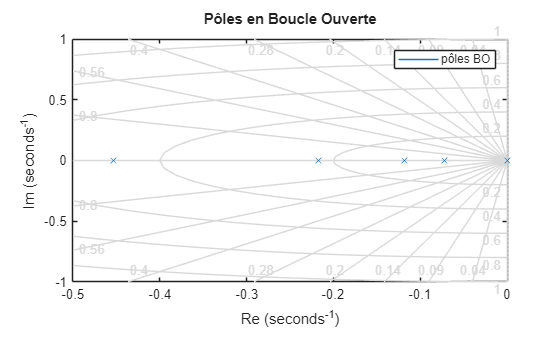

% Création du système en objet Matlab
sysBO = ss(A, B_mot, C, D);

% Affichage des pôles du système BO en pzplot
figure;
pzplot(sysBO);
title('Pôles en Boucle Ouverte'); xlabel('Re'); ylabel('Im'); grid on;
legend("pôles BO");


% Affichage des pôles du système en BO
disp(' '); damp(sysBO)

 
                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -7.25e-02     1.00e+00       7.25e-02         1.38e+01    
 -7.25e-02     1.00e+00       7.25e-02         1.38e+01    
 -1.18e-01     1.00e+00       1.18e-01         8.45e+00    
 -2.17e-01     1.00e+00       2.17e-01         4.60e+00    
 -4.53e-01     1.00e+00       4.53e-01         2.21e+00    
 -4.53e-01     1.00e+00       4.53e-01         2.21e+00    
